## Tarea 2

## Santiago Fernández Sáenz - C22943 

## Eyeri Méndez Méndez - C24765

### **Respuesta corta**

**1. **Describa un algoritmo para determinar los pesos $w_i$ de la fórmula de Newton-Cotes para $n = 3$ en el intervalo $[-1, 1]$, la cual viene dada por


$$$$ \int_{-1}^{1}f(x)dx \approx w_0f(-1) + w_1f(-1/3) + w_2f(1/3) + w_3f(1) $$$$


La fórmula de Newton-Cotes se basa en aproximar la función $f(x)$ mediante un polinomio interpolador que pasa por los puntos $(-1, -1/3, 1/3, 1)$. Así, utilizamos los puntos de cuadratura $x_0 = -1, x_1 = -1/3, x_2 = 1/3$ y $x_3 = 1$ para interpolar un polinomio de grado 3 y utilizar la integral de este polinomio como una aproximación de la integral de $f(x)$ en el intervalo $[-1, 1]$.

Por lo tanto, para determinar los pesos $w_i$, se necesita que la cuadratura sea exacta para polinomios de grado 3, es decir, los pesos deben satisfacer la condición de que al integrar los polinomios $1, x, x^2$ y $x^3$ con la cuadratura, los resultados sean iguales a las integrales exactas de estos polinomios en el intervalo $[-1, 1]$.

De esta manera, se tendría el siguiente sistema de ecuaciones:


$$(1) \int_{-1}^{1}1dx = 2 = w_0 + w_1 + w_2 + w_3$$



$$(2) \int_{-1}^{1}xdx = 0 = -w_0 - \frac{1}{3}w_1 + \frac{1}{3}w_2 + w_3$$



$$(3) \int_{-1}^{1}x^2dx = \frac{2}{3} = w_0 + \left(\frac{1}{3}\right)^2 w_1 + \left(\frac{1}{3}\right)^2 w_2 + w_3$$



$$(4) \int_{-1}^{1} x^3dx = 0 = -w_0 - \left(\frac{1}{3}\right)^3 w_1 + \left(\frac{1}{3}\right)^3 w_2 + w_3 \text{,}$$


el cual se podría resolver usando métodos numéricos o de álgebra lineal para determinar los pesos $w_i$.

**2. **Describa un método, con base en lo estudiado en clase, para aproximar la integral impropia 


$$I = \int_{0}^{1} \frac{sin(x)}{x^{3/2}} dx$$


de forma tal que pueda garantizar que el error es menor a una tolerancia dada.

Un método para aproximar la integral impropia $I$ es el de cuadratura adaptiva, que subdivide el intervalo de integración de forma adaptativa, concentrando más puntos donde la función varía rápidamente o tiene singularidades. En este caso, se dividiría el intervalo $[0, 1]$ en subintervalos más pequeños, especialmente en particiones más finas cerca de $x = 0$, que es donde el integrando presenta problemas.

De esta manera, se podría usar algún método de cuadratura numérica, por ejemplo Simpson, permitiendo calcular automáticamente una estimación del error en cada subintervalo. Así, se continuan subdividiendo los subintervalos hasta que el error de la integral sea menor que una tolerancia predefinida $\epsilon$.

**3.** En una regla de cuadratura en el intervalo $[0, 1]$ con $n + 1$ nodos, se fijan 3 nodos internos. ¿Cuál es el mayor grado de un polinomio que se puede integrar de manera exacta? Justifique de forma general.

Para determinar el mayor grado de un polinomio que se puede integrar de manera exacta, iniciamos con los casos que se han desarrollado durante las clases. En el caso de la cuadratura de Gauss, se tienen $n + 1$ nodos y $n + 1$ pesos a calcular, luego, se sabe que si $f \in \mathbb{P}_{2n + 1}$, la cuadratura da un resultado exacto.

El otro caso estudiado en clase fue Gauss-Lobatto, este funciona de manera similar a la cuadratura de Gauss, sin embargo, se fijan los nodos de los extremos, con lo cual quedan $n + 1$ pesos y $n - 1$ nodos, según lo visto en clase, esto resulta en que la cuadratura es exacta si $f \in \mathbb{P}_{2n - 1}$.

Con todo esto, se puede ver que la única diferencia son los nodos libres, pues, al fijar 2 nodos en la cuadratura se reduce en 2 el grado del mayor polinomio a aproximar de forma exacta. Siguiendo este patrón, si se fijan 3 nodos de la cuadratura, tendremos que esta es exacta si $f \in \mathbb{P}_{2n - 2}$.

De forma general, si se calculan los $n + 1$ pesos de la cuadratura y se cambia el número de nodos a $n + 1 - r$ (siendo $r$ los nodos fijados), tendremos que la fórmula de cuadratura es exacta si $f \in \mathbb{P}_{2n + 1 - r}$.

### **Desarrollo**

**Pregunta 1. **Considere $n + 2$ puntos, $\{(x_i, y_i)\}_{i = 0} ^ {n + 1}$ (donde los $x_i$ son distintos). Sea $q$ el polinomio de Lagrange de grado $n$ que interpola los puntos $\{(x_i, y_i)\}_{i = 0} ^ {n}$ y sea $r$ el polinomio de Lagrange de grado $n$ que interpola los puntos $\{(x_i, y_i)\}_{i = 1} ^ {n + 1}$. Defina:


$$p(x) := \frac{(x - x_0) \cdot r(x) - (x - x_{n + 1}) \cdot q(x)}{x_{n + 1} - x_0}$$


Demuestre que $p$ es el polinomio de grado $n + 1$ que interpola todo el conjunto de datos.

En primer lugar, de la definición de $q$ y $r$, se puede afirmar que:


$$r(x_i) = q(x_i) = f(x_i) \hspace{5cm} \forall i \in \{1, 2, \dots, n\} \hspace{1cm} (a)$$


Por lo cual, partiendo de la definición del polinomio, tenemos:


$$p(x_i) =  \frac{(x_i - x_0) \cdot r(x_i) - (x_i - x_{n + 1}) \cdot q(x_i)}{x_{n + 1} - x_0}$$



$$\Longrightarrow p(x_i) =  \frac{(x_i - x_0) \cdot f(x_i) - (x_i - x_{n + 1}) \cdot f(x_i)}{x_{n + 1} - x_0} \hspace{2cm} (a)$$



$$\Longrightarrow p(x_i) =  \frac{x_i \cdot f(x_i) - x_0 \cdot f(x_i) - x_i  \cdot f(x_i) + x_{n + 1} \cdot f(x_i)}{x_{n + 1} - x_0}$$



$$\Longrightarrow p(x_i) =  \frac{x_{n + 1} \cdot f(x_i) - x_0 \cdot f(x_i)}{x_{n + 1} - x_0}$$



$$\Longrightarrow p(x_i) =  \frac{f(x_i) \cdot (x_{n + 1} - x_0 )}{x_{n + 1} - x_0}$$



$$\Longrightarrow p(x_i) = f(x_i)$$


Con esto, queda probado para $i \in \{1, 2, \dots, n\}$, faltan los casos en donde $i \in \{0, n + 1\}$. Para $i = 0$, se tiene que:


$$q(x_0) = f(x_0)$$


Aunque no se sabe qué pasa exactamente en $r(x_0)$, note que:


$$p(x_0) =  \frac{(x_0 - x_0) \cdot r(x_0) - (x_0 - x_{n + 1}) \cdot q(x_0)}{x_{n + 1} - x_0}$$



$$\Longrightarrow p(x_0) =  \frac{0 \cdot r(x_0) - (x_0 - x_{n + 1}) \cdot q(x_0)}{x_{n + 1} - x_0}$$



$$\Longrightarrow p(x_0) =  \frac{- (x_0 - x_{n + 1}) \cdot q(x_0)}{x_{n + 1} - x_0}$$



$$\Longrightarrow p(x_0) =  \frac{(- x_0 + x_{n + 1}) \cdot q(x_0)}{x_{n + 1} - x_0}$$



$$\Longrightarrow p(x_0) =  \frac{(x_{n + 1} - x_0) \cdot q(x_0)}{x_{n + 1} - x_0}$$



$$\Longrightarrow p(x_0) = q(x_0)$$


Por lo cual se comprueba para $i = 0$, finalmente, el caso $i = n + 1$ es similar al anterior, pues:


$$p(x_{n + 1}) =  \frac{(x_{n + 1} - x_0) \cdot r(x_{n + 1}) - (x_{n + 1} - x_{n + 1}) \cdot q(x_{n + 1})}{x_{n + 1} - x_0}$$



$$\Longrightarrow p(x_{n + 1}) =  \frac{(x_{n + 1} - x_0) \cdot r(x_{n + 1}) - 0 \cdot q(x_{n + 1})}{x_{n + 1} - x_0}$$



$$\Longrightarrow p(x_{n + 1}) =  \frac{(x_{n + 1} - x_0) \cdot r(x_{n + 1})}{x_{n + 1} - x_0}$$



$$\Longrightarrow p(x_{n + 1}) =  r(x_{n + 1})$$


Y por la definición del problema:


$$r(x_{n + 1}) = f(x_{n + 1})$$


Es decir, se comprueba que el polinomio $p(x) := \frac{(x - x_0) \cdot r(x) - (x - x_{n + 1}) \cdot q(x)}{x_{n + 1} - x_0}$ interpola a todos los puntos $x_i, \hspace{0.1cm} i \in \{0, 1, \dots, n + 1 \}$.

**Pregunta 2.** En este ejercicio se demostrará cómo obtener la fórmula de Gauss de una forma diferente a la vista en clase. Dados $n$ natural, un intervalo $[a, b]$ y una función peso $w: (a, b) \to \mathbb{R}^+$, considere el polinomio ortogonal $\phi_{n+1}(x)$ de grado $n+1$. En clase demostramos que sus $n+1$ ceros, los cuales denotamos por $\{x_0, \dots, x_n\}$, son distintos y están en el intervalo $(a, b)$.

$a)$ Sea $p$ un polinomio de grado a lo sumo $2n+1$. Por el algoritmo de la división, es posible escribir $p(x) = \phi_{n+1}(x) q(x) + r(x)$, para polinomios apropiados $q, r$. Demuestre que


$$\int_{a}^{b} p(x) w(x) dx = \int_{a}^{b} r(x) w(x) dx$$


Para que $p(x)$ sea un polinomio de grado a lo sumo $2n+1$, $q(x)$ tiene que ser un polonimio de grado $n$ y $r(x)$ un polinomio de grado a lo sumo $n$.

Sabemos que los polinomios ortogonales $\phi_0(x), \phi_1(x), \dots, \phi_n(x)$ son linealmente independientes, por lo que podemos expresar $q(x)$ a partir de ellos:


$$q(x) = a_0 \cdot \phi_0(x) + a_1 \cdot \phi_1(x) + \dots + a_n \cdot \phi_n(x)$$


Es decir, $q(x)$ es una combinación lineal de de los polinomios ortogonales $\{ \phi_i \}_{i = 0}^{n}$. Además, como $( \phi_{n+1}, \phi_j)_w = 0, \forall j \leq n$, entonces se tiene que


$$(\phi_{n+1}, q)_w = \int_{a}^{b} \phi_{n+1}(x) q(x) w(x) dx = 0$$


Así, note que:


$$p(x) = \phi_{n+1}(x) q(x) + r(x) \Rightarrow \int_{a}^{b} p(x) w(x) dx = \int_{a}^{b} [ \phi_{n+1}(x) q(x) + r(x) ] w(x) dx =$$



$$= \int_{a}^{b} \phi_{n+1}(x) q(x) w(x) dx + \int_{a}^{b} r(x) w(x) dx = \int_{a}^{b} r(x) w(x) dx$$


$b)$  Exprese $r$ como combinación lineal de los polinomios de Lagrange $\{L_i\}_{i=0}^{n}$ (asociados a los nodos $\{x_0, \dots, x_n\}$). Justifique por qué esto es posible.

Dado que $r(x) $ es un polinomio de grado a lo sumo $n$, podemos escribirlo como una combinación lineal de los polinomios de Lagrange:


$$r(x) = \sum_{i = 0}^{n} r(x_i) L_i(x),$$


donde $r(x_i)$ son los valores del polinomio $r(x)$ en los nodos $x_i$, con $i \in \{0, 1, \dots, n\}$.

Esta representación es posible porque los polinomios de Lagrange $\{L_i\}_{i=0}^{n}$ forman una base para el espacio de polinomios de grado a lo sumo $n$. Es decir, cualquier polinomio de grado $n$ o menor puede escribirse de manera única como una combinación lineal de estos polinomios.

Además, como los $L_i$ están definidos en los puntos $x_0, x_1, \dots, x_n$, podemos usar los valores de $r(x) $ en esos puntos, $r(x_0), r(x_1), \dots, r(x_n)$, como coeficientes en la combinación lineal, siendo esta una combinación lineal válida de los polinomios de Lagrange que reconstruye $r(x)$ en el intervalo dado.

$c)$  Demuestre que 


$$\int_{a}^{b} p(x) w(x) dx = \sum_{i=0}^{n} w_i p(x_i)$$


para valores apropiados de $\{w_i\}_{i=0}^{n}$. Dé explícitamente la fórmula para cada $w_i$. ¿Coincide con la fórmula dada en clase?

Del inciso anterior tenemos que


$$r(x) = \sum_{i = 0}^{n} r(x_i) L_i(x) \Rightarrow \int_{a}^{b} r(x) w(x) dx = \int_{a}^{b} \sum_{i = 0}^{n} r(x_i) L_i(x) w(x) dx = \sum_{i = 0}^{n} r(x_i) \int_{a}^{b} L_i(x) w(x) dx$$


Ahora bien, como $\{x_0, x_1, \dots, x_n\}$ son los $n+1$ ceros (distintos) del polinomio ortogonal $\phi_{n+1}(x)$ en el intervalo $(a, b)$, entonces $p(x_i) = \phi_{n+1}(x_i) q(x_i) + r(x_i) = 0 + r(x_i) = r(x_i), \forall i \in \{0, 1, \dots, n\}$. 

De esta manera, junto a lo obtenido en el inciso $a)$, se tiene que


$$\int_{a}^{b} p(x) w(x) dx = \int_{a}^{b} r(x) w(x) dx = \sum_{i = 0}^{n} r(x_i) w_i = \sum_{i = 0}^{n} p(x_i) w_i \text{, donde } w_i = \int_{a}^{b} L_i(x) w(x) dx$$


Esta fórmula no coincide con la dada en clase ya que en esta última se tiene que 


$$w_i = \int_{a}^{b} L_i^2(x) w(x) dx$$


Es decir, en la nueva fórmula encontrada no se eleva al cuadrado los polinomios de Lagrange $L_i(x)$, por lo que puede resultar más conveniente utilizarla.

$d)$ Concluya que la cuadratura 


$$\sum_{i=0}^{n} w_i p(x_i)$$


es exacta para cualquier polinomio de grado a lo sumo $2n+1$.

Sabemos que cualquier polinomio $p(x)$ de grado $2n+1$ se puede descomponer en $\phi_{n+1}(x) q(x) + r(x)$, donde $q(x)$ es de grado $n$ y $r(x)$ es de grado a lo sumo $n$. Dado que el término $\phi_{n+1}(x) q(x)$ se anula al integrarlo respecto a la función peso $w(x)$, este término no contribuye a la integral de $p(x)$; así, esta se reduce a la integral de $r(x)$ respecto a la función peso $w(x)$. Como ya se demostró que la cuadratura 


$$\int_{a}^{b} r(x) w(x) dx = \sum_{i=0}^{n}p(x_i) w_i$$


es exacta para $r(x)$, concluimos que dicha cuadratura es exacta para cualquier polinomio $p(x)$ de grado a lo sumo $2n+1$.

**Pregunta 3. **

En este ejercicio se deducirá una manera diferente para definir los nodos y pesos de la cuadratura de Gauss. Considere un conjunto de polinomios ortogonales mónicos $$\lbrace \phi_j\rbrace_{j=0}^\infty$$ en el intervalo $$[a,b]$$, correspondientes a una función peso $$w(x)$$.

**a)**

Considere: 


$$\phi_{k+1}(x) = (x-b_k) \cdot \phi_k(x) - a_k \cdot \phi_{k-1}(x)\ \forall\ k\geq 1.  \hspace{2cm} (*)$$


Se sabe que esto es un polinomio mónico, pues, el polinomio $\phi_k(x)$ es mónico, luego, al multiplicar $x$ este sigue siendo mónico.

Por algoritmo de la división, para cada  $$k\geq 1$
$se tiene que $$\phi_{k+1}(x)-x \phi_k(x)$ $es un polinomio de grado $k$. Luego, se tiene que $<\phi_0, \phi_1, \dots, \phi_k>$ son una base de los polinomios de grado $k$, por lo cual se puede expresar lo siguiente:


$$\phi_{k + 1} - x \cdot \phi_k = -b_k \cdot \phi_k - a_k \cdot\phi_{k - 1} + \sum_{i = 0} ^ {k - 2} c_i \cdot \phi_i$$



$$\Longrightarrow \phi_{k + 1} - x \cdot \phi_k = -b_k \cdot \phi_k - a_k \cdot\phi_{k - 1} + \sum_{i = 0} ^ {k - 2} c_i \cdot \phi_i \cdot \prod_{j = 0} ^ {k - 2} 
\left( \frac{\int_a^b \phi_j \cdot w(x) \hspace{0.1cm} dx}{\int_a^b \phi_j \cdot w(x) \hspace{0.1cm} dx} \right)$$



$$\Longrightarrow \phi_{k + 1} - x \cdot \phi_k = -b_k \cdot \phi_k - a_k \cdot\phi_{k - 1} + \sum_{i = 0} ^ {k - 2} c_i \cdot  \prod_{j = 0} ^ {k - 2} 
\left( \frac{\int_a^b \phi_i \cdot \phi_j \cdot w(x) \hspace{0.1cm} dx}{\int_a^b \phi_j \cdot w(x) \hspace{0.1cm} dx} \right)$$


Sin embargo, en cada término de la suma existe más de un $j$ de la forma $j \neq i$, de forma que la ortogonalidad de los polinomios $\phi_k$ hace que $\int_a^b \phi_i \cdot \phi_j \cdot w(x) \hspace{0.1cm} dx = 0$, es decir, toda la sumatoria equivale a 0. Queda:


$$\Longrightarrow \phi_{k + 1} - x \cdot \phi_k = -b_k \cdot \phi_k - a_k \cdot\phi_{k - 1}$$



$$\Longrightarrow \phi_{k + 1} = x \cdot \phi_k -b_k \cdot \phi_k - a_k \cdot\phi_{k - 1}$$



$$\Longrightarrow \phi_{k+1}(x) = (x-b_k) \cdot \phi_k(x) - a_k \cdot \phi_{k-1}(x)$$


Con lo cual se demuestra la igualdad $(*)$.

Posteriormente, note que, de $(*)$:


$$\phi_{k+1}(x) = (x-b_k) \cdot \phi_k(x) - a_k \cdot \phi_{k-1}(x)$$



$$\Longrightarrow \phi_{k+1}(x) \cdot \phi_k (x) \cdot w (x) = \left[(x-b_k) \cdot \phi_k(x) - a_k \cdot \phi_{k-1}(x)\right] \cdot \phi_k (x) \cdot w (x)$$



$$\Longrightarrow \int_{a}^b \phi_{k+1}(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx = \int_{a}^b \left[(x-b_k) \cdot \phi_k(x) - a_k \cdot \phi_{k-1}(x)\right] \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx$$


Note que, por definición de ortogonalidad $\int_{a}^b \phi_{k+1}(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx = 0$, entonces:


$$\Longrightarrow 0 = \int_{a}^b \left[(x-b_k) \cdot \phi_k(x) - a_k \cdot \phi_{k-1}(x)\right] \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow 0 = \int_{a}^b (x-b_k) \cdot \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx - \int_{a}^b a_k \cdot \phi_{k-1}(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow 0 = \int_{a}^b (x-b_k) \cdot \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx - a_k \int_{a}^b \phi_{k-1}(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx$$


Como son ortogonales, $\int_{a}^b \phi_{k}(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx = 0$, se sigue que:


$$\Longrightarrow 0 = \int_{a}^b (x-b_k) \cdot \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow 0 = \int_{a}^b x \cdot \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx - \int_{a}^b b_k \cdot \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow 0 = \int_{a}^b x \cdot \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx - b_k \int_{a}^b \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow - \int_{a}^b x \cdot \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx = - b_k \int_{a}^b \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow \int_{a}^b x \cdot \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx = b_k \int_{a}^b \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow b_k = \frac{ \int_{a}^b x \cdot \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx}{\int_{a}^b \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx}$$



$$\Longrightarrow b_k = \frac{(x, \phi_k ^ 2 (x) )_w}{||\phi_k(x)|| ^ 2}$$


Por otro lado, igualmente partiendo de $(*)$:


$$\phi_{k+1}(x) = (x-b_k) \cdot \phi_k(x) - a_k \cdot \phi_{k-1}(x)$$



$$\Longrightarrow \phi_{k+1}(x) \cdot \phi_{k-1} (x) \cdot w (x) = \left[(x-b_k) \cdot \phi_k(x) - a_k \cdot \phi_{k-1}(x)\right] \cdot \phi_{k - 1} (x) \cdot w (x)$$



$$\Longrightarrow \int_a^b \phi_{k+1}(x) \cdot \phi_{k-1} (x) \cdot w (x) \hspace{0.1cm} dx = \int_a^b \left[(x-b_k) \cdot \phi_k(x) - a_k \cdot \phi_{k-1}(x)\right] \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx$$


Nuevamente, note que, por ortogonalidad $\int_a^b \phi_{k+1}(x) \cdot \phi_{k-1} (x) \cdot w (x) \hspace{0.1cm} dx = 0$, luego:


$$\Longrightarrow 0 = \int_a^b \left[(x-b_k) \cdot \phi_k(x) - a_k \cdot \phi_{k-1}(x)\right] \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow 0 = \int_a^b (x-b_k) \cdot \phi_k(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx - \int_a^b a_k \cdot \phi_{k-1}(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow 0 = \int_a^b (x-b_k) \cdot \phi_k(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx - \int_a^b a_k \cdot \phi_{k-1}(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow 0 = \int_a^b x \cdot \phi_k(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx - b_k \int_a^b \phi_k(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx  - \int_a^b a_k \cdot \phi_{k-1}(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx$$


Una vez más, por ortogonalidad $\int_{a}^b \phi_{k}(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx = 0$, con lo que queda:


$$\Longrightarrow 0 = \int_a^b x \cdot \phi_k(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx   - \int_a^b a_k \cdot \phi_{k-1}(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow 0 = \int_a^b x \cdot \phi_k(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx - a_k \int_a^b \phi_{k-1}(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow - \int_a^b x \cdot \phi_k(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx = - a_k \int_a^b \phi_{k-1}(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow \int_a^b x \cdot \phi_k(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx = a_k \int_a^b \phi_{k-1}(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx$$



$$\Longrightarrow a_k = \frac{\int_a^b x \cdot \phi_k(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx}{\int_a^b \phi_{k-1}(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx}$$


$a_k = \frac{(x, f(x))_w}{||\phi_k (x)|| ^ 2}$, donde $ f(x) = \phi_k(x) \cdot \phi_{k - 1}(x)$

$\therefore$ Se cumple la recursión del inicio, en la cual:


$$\phi_1(x) = (x - b_0) \cdot \phi_0(x)$$



$$\phi_{k+1}(x) = \left(x -  \frac{(x, \phi_k(x) ^ 2)_w}{||\phi_k(x)|| ^ 2}\right) \cdot \phi_k(x) - \left(\frac{(x, f(x))_w}{||\phi_k (x)|| ^ 2} \right) \cdot \phi_{k-1}(x)$$


**b)**

Usando la igualdad $\phi_k = \|\phi_k\| \cdot \widetilde{\phi}_k$, note que:


$$\alpha_1 \cdot \widetilde{\phi}_1(x) + \beta_0 \cdot \widetilde{\phi}_0(x) = x \cdot \widetilde{\phi}_0(x)$$



$$\Longrightarrow \alpha_1 \cdot \widetilde{\phi}_1(x)  = x \cdot \widetilde{\phi}_0(x) - \beta_0 \cdot \widetilde{\phi}_0(x)$$



$$\Longrightarrow \alpha_1 \cdot \widetilde{\phi}_1(x)  = \widetilde{\phi}_0(x) \cdot (x - \beta_0)$$



$$\Longrightarrow \alpha_1 \cdot \frac{\phi_1(x)}{||\phi_1 (x)||}  = \frac{\phi_0(x)}{||\phi_0 (x)||} \cdot (x - \beta_0)$$


Por los resultados del inciso anterior:


$$\Longrightarrow \alpha_1 \cdot \frac{(x - b_0)}{||\phi_1 (x)||}  = \frac{1}{||\phi_0 (x)||} \cdot (x - \beta_0)$$



$$\Longrightarrow \frac{(\alpha_1 \cdot x - \alpha_1 \cdot b_0)}{||\phi_1 (x)||}  = \left(\frac{1}{||\phi_0 (x)||} \cdot x - \frac{1}{||\phi_0 (x)||} \cdot\beta_0 \right)$$


Para que coincidan las constantes de $x$, necesariamente $\alpha_1 = \frac{||\phi_1(x)||}{||\phi_0(x)||}$, nos queda.


$$\Longrightarrow \frac{\left(\frac{||\phi_1(x)||}{||\phi_0(x)||} \cdot x - \frac{||\phi_1(x)||}{||\phi_0(x)||} \cdot b_0 \right)}{||\phi_1 (x)||}  = \left(\frac{1}{||\phi_0 (x)||} \cdot x - \frac{1}{||\phi_0 (x)||} \cdot\beta_0 \right)$$



$$\Longrightarrow  \left(\frac{1}{||\phi_0 (x)||} \cdot x -\frac{b_0}{||\phi_0 (x)||} \right)  = \left(\frac{1}{||\phi_0 (x)||} \cdot x - \frac{1}{||\phi_0 (x)||} \cdot\beta_0 \right)$$


Por lo cual, nos queda que $\beta_0 = b_0$.

Para el caso general, considere:


$$\alpha_{k+1} \cdot \widetilde{\phi}_{k+1}(x) + \beta_k \cdot \widetilde{\phi}_k(x) + \alpha_{k} \cdot \widetilde{\phi}_{k-1}(x) = x \cdot \widetilde{\phi}_k(x)$$



$$\Longrightarrow \alpha_{k+1} \cdot \widetilde{\phi}_{k+1}(x) = x \cdot \widetilde{\phi}_k(x) - \beta_k \cdot \widetilde{\phi}_k(x) - \alpha_{k} \cdot \widetilde{\phi}_{k-1}(x)$$



$$\Longrightarrow \alpha_{k+1} \cdot \widetilde{\phi}_{k+1}(x) = \widetilde{\phi}_k(x) \cdot (x - \beta_k) - \alpha_{k} \cdot \widetilde{\phi}_{k-1}(x)$$



$$\Longrightarrow \alpha_{k+1} \cdot \widetilde{\phi}_{k+1}(x) \cdot \phi_k (x) \cdot w(x)= \widetilde{\phi}_k(x) \cdot (x - \beta_k) \cdot \phi_k (x) \cdot w(x) - \alpha_{k} \cdot \widetilde{\phi}_{k-1}(x) \cdot \phi_k (x) \cdot w(x)$$



$$\Longrightarrow \alpha_{k+1} \cdot \frac{\phi_{k + 1}}{||\phi_{k + 1}||} \cdot \phi_k (x) \cdot w(x)= \frac{\phi_{k}}{||\phi_{k}||} \cdot (x - \beta_k) \cdot \phi_k (x) \cdot w(x) - \alpha_{k} \cdot\frac{\phi_{k - 1}}{||\phi_{k - 1}||} \cdot \phi_k (x) \cdot w(x)$$



$$\Longrightarrow \frac{\alpha_{k+1}}{||\phi_{k + 1}||} \int_a^b  \phi_{k + 1} \cdot \phi_k (x) \cdot w(x) \hspace{0.1cm} dx = \frac{1}{||\phi_{k}||} \int_a^b \phi_k \cdot (x - \beta_k) \cdot \phi_k (x) \cdot w(x) \hspace{0.1cm} dx - \frac{\alpha_{k}}{||\phi_{k - 1}||} \cdot \int_a^b \phi_{k - 1} \cdot \phi_k (x) \cdot w(x) \hspace{0.1cm} dx$$


Por ortogonalidad, $\int_{a}^b \phi_{k+1}(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx = 0$ y $\int_{a}^b \phi_{k}(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx = 0$, nos queda:


$$\Longrightarrow 0 = \frac{1}{||\phi_{k}||} \int_a^b \phi_k \cdot (x - \beta_k) \cdot \phi_k (x) \cdot w(x) \hspace{0.1cm} dx$$



$$\Longrightarrow 0 = \int_a^b \phi_k \cdot x \cdot \phi_k (x) \cdot w(x) \hspace{0.1cm} dx - \beta_k \int_a^b \phi_k \cdot \phi_k (x) \cdot w(x) \hspace{0.1cm} dx$$



$$\Longrightarrow -\int_a^b \phi_k \cdot x \cdot \phi_k (x) \cdot w(x) \hspace{0.1cm} dx = - \beta_k \int_a^b \phi_k \cdot \phi_k (x) \cdot w(x) \hspace{0.1cm} dx$$



$$\Longrightarrow \int_a^b \phi_k \cdot x \cdot \phi_k (x) \cdot w(x) \hspace{0.1cm} dx = \beta_k \int_a^b \phi_k \cdot \phi_k (x) \cdot w(x) \hspace{0.1cm} dx$$



$$\Longrightarrow \beta_k =  \frac{\int_a^b \phi_k \cdot x \cdot \phi_k (x) \cdot w(x) \hspace{0.1cm} dx}{\int_a^b \phi_k \cdot \phi_k (x) \cdot w(x) \hspace{0.1cm} dx}$$



$$\Longrightarrow \beta_k = \frac{(x, \phi_k^2)_w}{||\phi_k(x)|| ^ 2}$$


Por otro lado, con $\alpha_k$, el problema es similar, de forma que (multiplico $\phi_{k - 1} (x)$ a ambos lados):


$$\alpha_{k+1} \cdot \widetilde{\phi}_{k+1}(x) = \widetilde{\phi}_k(x) \cdot (x - \beta_k) - \alpha_{k} \cdot \widetilde{\phi}_{k-1}(x)$$



$$\Longrightarrow \alpha_{k+1} \cdot \widetilde{\phi}_{k+1}(x) = \widetilde{\phi}_k(x) \cdot (x - \beta_k) - \alpha_{k} \cdot \widetilde{\phi}_{k-1}(x)$$



$$\Longrightarrow \alpha_{k+1} \cdot \frac{\phi_{k + 1}}{||\phi_{k + 1}||} \cdot \phi_{k - 1} (x) \cdot w(x) =\frac{\phi_{k}}{||\phi_{k}||} \cdot (x - \beta_k) \cdot \phi_{k - 1} (x) \cdot w(x) - \alpha_{k} \cdot \frac{\phi_{k - 1}}{||\phi_{k - 1}||} \cdot \phi_{k - 1} (x) \cdot w(x)$$



$$\Longrightarrow \frac{\alpha_{k+1}}{||\phi_{k + 1}||} \int_a^b  \phi_{k + 1} \cdot \phi_{k - 1} (x) \cdot w(x) \hspace{0.1cm} dx = \frac{1}{||\phi_{k}||} \int_a^b \phi_{k} \cdot (x - \beta_k) \cdot \phi_{k - 1} (x) \cdot w(x) \hspace{0.1cm} dx - \frac{\alpha_{k}}{||\phi_{k - 1}||} \int_a^b \phi_{k - 1} \cdot \phi_{k - 1} (x) \cdot w(x) \hspace{0.1cm} dx$$


Por ortogonalidad, $\int_a^b  \phi_{k + 1} \cdot \phi_{k - 1} (x) \cdot w(x) \hspace{0.1cm} dx = 0$, entonces:


$$\Longrightarrow 0 = \frac{1}{||\phi_{k}||} \int_a^b \phi_{k} \cdot (x - \beta_k) \cdot \phi_{k - 1} (x) \cdot w(x) \hspace{0.1cm} dx - \frac{\alpha_{k}}{||\phi_{k - 1}||} \int_a^b \phi_{k - 1} \cdot \phi_{k - 1} (x) \cdot w(x) \hspace{0.1cm} dx$$



$$\Longrightarrow 0 = \frac{1}{||\phi_{k}||} \int_a^b \phi_{k}  \cdot \phi_{k - 1} (x) \cdot w(x) \cdot x \hspace{0.1cm} dx - \int_a^b \phi_{k}  \cdot \phi_{k - 1} (x) \cdot w(x) \cdot \beta_k \hspace{0.1cm} dx - \frac{\alpha_{k}}{||\phi_{k - 1}||} \int_a^b \phi_{k - 1} \cdot \phi_{k - 1} (x) \cdot w(x) \hspace{0.1cm} dx$$


Por ortogonalidad, $\int_a^b  \phi_{k} \cdot \phi_{k - 1} (x) \cdot w(x) \hspace{0.1cm} dx = 0$, entonces:


$$\Longrightarrow 0 = \frac{1}{||\phi_{k}||} \int_a^b \phi_{k}  \cdot \phi_{k - 1} (x) \cdot w(x) \cdot x \hspace{0.1cm} dx - \frac{\alpha_{k}}{||\phi_{k - 1}||} \int_a^b \phi_{k - 1} \cdot \phi_{k - 1} (x) \cdot w(x) \hspace{0.1cm} dx$$



$$\Longrightarrow \frac{\alpha_{k}}{||\phi_{k - 1}||} \int_a^b \phi_{k - 1} \cdot \phi_{k - 1} (x) \cdot w(x) \hspace{0.1cm} dx = \frac{1}{||\phi_{k}||} \int_a^b \phi_{k}  \cdot \phi_{k - 1} (x) \cdot w(x) \cdot x \hspace{0.1cm} dx$$



$$\Longrightarrow \alpha_k = \frac{||\phi_{k - 1}||}{||\phi_{k}||} \cdot \frac{\int_a^b \phi_{k}  \cdot \phi_{k - 1} (x) \cdot w(x) \cdot x \hspace{0.1cm} dx}{\int_a^b \phi_{k - 1} \cdot \phi_{k - 1} (x) \cdot w(x) \hspace{0.1cm} dx}$$



$$\Longrightarrow \alpha_k = \frac{||\phi_{k - 1}||}{||\phi_{k}||} \cdot \frac{\int_a^b \phi_{k}  \cdot \phi_{k - 1} (x) \cdot w(x) \cdot x \hspace{0.1cm} dx}{||\phi_{k - 1}|| ^ 2}$$



$$\Longrightarrow \alpha_k = \frac{\int_a^b \phi_{k}  \cdot \phi_{k - 1} (x) \cdot w(x) \cdot x \hspace{0.1cm} dx}{||\phi_{k - 1}|| \cdot ||\phi_{k}||}$$


$\Longrightarrow \alpha_k = \frac{(x, f(x))_w}{||\phi_{k - 1}|| \cdot ||\phi_{k}||}$, con $ f(x) = \phi_k(x) \cdot \phi_{k - 1}(x)$

**c)**

Evaluando $x_j$ en $(1)$, obtenemos:


$$\alpha_{k+1} \cdot \widetilde{\phi}_{k+1}(x_j) + \beta_k \cdot \widetilde{\phi}_k(x_j) + \alpha_{k} \cdot \widetilde{\phi}_{k-1}(x_j) = x \cdot \widetilde{\phi}_k(x_j)$$


Y como $x_j$ es un cero del polinomio $\widetilde{\phi}_{n+1}$, entonces:


$$\alpha_{n+1} \cdot \widetilde{\phi}_{n+1}(x_j) + \beta_n \cdot \widetilde{\phi}_n(x_j) + \alpha_{n} \cdot \widetilde{\phi}_{n-1}(x_j) = x \cdot \widetilde{\phi}_n(x_j)$$



$$\Longrightarrow \beta_n \cdot \widetilde{\phi}_n(x_j) + \alpha_{n} \cdot \widetilde{\phi}_{n-1}(x_j) = x \cdot \widetilde{\phi}_n(x_j)$$


En este caso, vamos a probar que:


$$T \cdot v = x \cdot v$$


en donde $v = [\widetilde{\phi}_0 (x_j) \hspace{0.1cm} \widetilde{\phi}_1(x_j) \cdots \widetilde{\phi}_n (x_j) ] ^ T$.

Inicialmente, con el lado de la matriz $T$, tendríamos:


$$\left[
\begin{array}{llllll}
\beta_0 & \alpha_1 &  &  &  &  \\ 
\alpha_1 & \beta_1 & \alpha_2 &  &  &  \\ & \alpha_2 & \beta_2 & \alpha_3 &  &  \\  &  & \ddots & \ddots & \ddots &  \\ &  &  & \alpha_{n-1} & \beta_{n-1} & \alpha_{n} \\ &  &  &  & \alpha_n & \beta_n \end{array} \right]

\cdot 
\left[
\begin{array}{llllll}
\widetilde{\phi}_0 (x_j)  \\ 
\widetilde{\phi}_1(x_j)  \\
\widetilde{\phi}_2(x_j)  \\
\hspace{0.275cm} \vdots \\ 
\widetilde{\phi}_{n}(x_{j}) 
\end{array} \right]$$


Si realizamos esta multiplicación matricial nos queda como primer término:


$$\alpha_1 \cdot \widetilde{\phi}_1(x_j) + \beta_0 \cdot \widetilde{\phi}_0(x_j)$$


Como segundo término:


$$\alpha_{2} \cdot \widetilde{\phi}_{2}(x_j) + \beta_1 \cdot \widetilde{\phi}_1(x_j) + \alpha_{1} \cdot \widetilde{\phi}_{0}(x_j)$$


Y en general, cada uno de los términos (con excepción del primero) se puede expresar como:


$$\alpha_{k+1} \cdot \widetilde{\phi}_{k+1}(x_{j}) + \beta_k \cdot \widetilde{\phi}_k(x_j) + \alpha_{k} \cdot \widetilde{\phi}_{k-1}(x_{j})$$


Por otro lado, note que:


$$x \cdot v$$



$$= x \cdot [\widetilde{\phi}_0 (x_j) \hspace{0.1cm} \widetilde{\phi}_1(x_j) \cdots \widetilde{\phi}_n (x_j) ] ^ T$$


En este caso, el primer producto sería:


$$x \cdot \widetilde{\phi}_0(x_j)$$


El segundo:


$$x \cdot \widetilde{\phi}_1(x_j)$$


Y en general quedaría:


$$x \cdot \widetilde{\phi}_k(x_j)$$


Juntando los 2 lados de la igualdad, entonces, tendríamos que el primer caso es:


$$\alpha_1 \cdot \widetilde{\phi}_1(x_j) + \beta_0 \cdot \widetilde{\phi}_0(x_j) = x \cdot \widetilde{\phi}_0(x_j)$$


En general tendríamos:


$$\alpha_{k+1} \cdot \widetilde{\phi}_{k+1}(x_j) + \beta_k \cdot \widetilde{\phi}_k(x_j) + \alpha_{k} \cdot \widetilde{\phi}_{k-1}(x_j) = x \cdot \widetilde{\phi}_k(x_j)$$


Y note que, estas últimas 2 ecuaciones son las que probamos en el inciso anterior, por lo cual conocemos que son verdaderas. Luego, volviendo al producto correspondiente, note que:


$$T \cdot v = x \cdot v$$


Esto nos dice que, por definición, $x$ es un valor propio de la matriz $T$, además, este coincide con los ceros del polinomio $\widetilde{\phi}_{k+1}(x)$, por lo que se demuestra el enunciado.

**d)**

En primer lugar, note que:


$$\delta_{ij} = \sum_{k=0}^n w_k \cdot \widetilde{\phi}_i(x_k) \cdot \widetilde{\phi}_j(x_k)$$



$$= \int_a^b \widetilde{\phi}_i(x) \cdot \widetilde{\phi}_j(x) \cdot w(x) \hspace{0.1cm} dx$$


ya que la cuadratura de Gauss es exacta para este caso.

En caso de que $i \neq j$, se aplica la ortogonalidad de los polinomios, por lo que:


$$\int_a^b \widetilde{\phi}_i(x) \cdot \widetilde{\phi}_j(x) \cdot w(x) \hspace{0.1cm} dx = 0$$


Por otro lado, si $i = j$, note que:


$$\int_a^b \widetilde{\phi}_j^2(x) \cdot w(x) \hspace{0.1cm} dx$$



$$= \int_a^b \frac{\phi_j^2(x)}{||\phi_j|| ^ 2} \cdot w(x) \hspace{0.1cm} dx$$



$$= \frac{1}{||\phi_j|| ^ 2} \int_a^b \phi_j^2(x) \cdot w(x) \hspace{0.1cm} dx \hspace{2cm} (**)$$


Pero note que $\int_a^b \phi_j^2(x) \cdot w(x) \hspace{0.1cm} dx = ||\phi_j||^2$, entonces:


$$(**) = 1$$


Por lo cual:


$$\delta_{ij} = \sum_{k=0}^n w_k \cdot \widetilde{\phi}_i(x_k) \cdot \widetilde{\phi}_j(x_k) = 
        \left\{ 
        \begin{array}{ll}
        1 & \mbox{si $i = j$} \\
        0 & \mbox{si $i \neq j$} \\
        \end{array}
        \right.$$


Por otro lado, note que:


$$p_{ij}^T \cdot w_{ij} \cdot p_{ij} = \sum_{k=0}^n w_k \cdot \widetilde{\phi}_i(x_k) \cdot \widetilde{\phi}_j(x_k) \hspace{0.5cm} \forall i, j \in \{0, 1, \dots, n \}$$


Pero recuerde de la definición que se probó anteriormente que:


$$\sum_{k=0}^n w_k \cdot \widetilde{\phi}_i(x_k) \cdot \widetilde{\phi}_j(x_k) = 
        \left\{ 
        \begin{array}{ll}
        1 & \mbox{si $i = j$} \\
        0 & \mbox{si $i \neq j$} \\
        \end{array}
        \right.$$



$$\therefore p_{ij}^T \cdot w_{ij} \cdot p_{ij} = \left\{ 
        \begin{array}{ll}
        1 & \mbox{si $i = j$} \\
        0 & \mbox{si $i \neq j$} \\
        \end{array}
        \right.$$


Lo cual es la definición de la identidad.

**e)**

Considere la matriz $W ^ {-1}$, usando Gauss-Jordan, es claro que:


$$\left[
\begin{array}{llllll}
\frac{1}{w}_0   \\ 
& \frac{1}{w}_1 \\
& & \ddots & &  \\ 
&  &  & \frac{1}{w}_n \end{array} \right]$$


Por otro lado, considere la matriz $P \cdot P ^ T$, la cual viene dada por:


$$\left[
\begin{array}{ccc}
\widetilde{\phi}_0(x_0) &  \ldots  & \widetilde{\phi}_n(x_0)   \\ 
\vdots & \ddots & \vdots \\ 
\widetilde{\phi}_0(x_n)  & \ldots  &\widetilde{\phi}_n(x_n) 
\end{array} 
\right]

\cdot

\left[
\begin{array}{ccc}
\widetilde{\phi}_0(x_0) &  \ldots  & \widetilde{\phi}_n(x_0)   \\ 
\vdots & \ddots & \vdots \\ 
\widetilde{\phi}_0(x_n)  & \ldots  &\widetilde{\phi}_n(x_n) 
\end{array} 
\right] ^ T$$


La entrada $(i, j)$ de la matriz $P \cdot P ^ T$ viene dada por:


$$\sum_{i = 0} ^ {n} \widetilde{\phi_j}(x_i) \cdot \widetilde{\phi_i}(x_j)$$


Y la entrada $(i, j)$ de la matriz $W ^ {-1}$ sería:


$$\left\{ 
        \begin{array}{ll}
        \frac{1}{w_j} & \mbox{si $i = j$} \\
        0 & \mbox{si $i \neq j$} \\
        \end{array}
        \right.$$


Luego, cuando $i = j$ se tiene que:


$$\frac{1}{w_j} = \sum_{i = 0} ^ {n} \widetilde{\phi_j}(x_i) \cdot \widetilde{\phi_i}(x_j)$$



$$\Longrightarrow \frac{1}{w_j} = \sum_{i = 0} ^ {n} (\widetilde{\phi_i }(x_j)) ^ 2$$


**f)**

Considere el vector propio $v$ asociado al valor propio $x_j$, el cual es equivalente al definido en el inciso `c`:


$$v = [\widetilde{\phi}_0 (x_j) \hspace{0.1cm} \widetilde{\phi}_1(x_j) \cdots \widetilde{\phi}_n (x_j) ] ^ T$$


Por otro lado, se sabe que la multiplicación de un escalar distinto de 0 por un vector propio sigue siendo un vector propio, más aún, este está asociado al mismo valor que el vector propio original, en este caso, $x_j$.

Por lo tanto, si multiplicamos $v $ por $\frac{1}{||v||}$, obtenemos un vector propio unitario $v ^ {(j)}$, el cual está asociado al nodo $x_j$.

Es decir, existe una constante $C \neq 0$ tal que: 

$v ^ {(j)} = C \cdot v = [v_1^{(j)},\ldots,v_{n+1}^{(j)}]^T$.

**g)**

Note que:


$$\phi_0 (x_j) = 1$$



$$\Longrightarrow \phi_0 (x_j) \cdot \frac{||\phi_0||}{||\phi_0||} = 1$$


Recuerde que $\widetilde{\phi_0} (x_j) = \frac{\phi_0 (x_j)}{||\phi_0||}$, entonces


$$\Longrightarrow \widetilde{\phi_0} (x_j) \cdot ||\phi_0|| = 1 \hspace{0.5cm} (**)$$


Pero: 


$$||\phi_0|| = (\phi_0, \phi_0)_w ^ {1 / 2}$$



$$= \left(\int_a^b w(x) \cdot \phi_0 ^ 2 (x_j) \hspace{0.1cm} dx \right) ^ {1 / 2}$$


Y recuerde que $\phi_0 ^ 2 (x_j) = 1$, con lo que queda:


$$= \left(\int_a^b w(x) \hspace{0.1cm} dx \right) ^ {1 / 2}$$


$= \sqrt{\mu}$, con $\mu = \int_a^b w(x) \hspace{0.1cm} dx$

Luego, volviendo a $(**)$:


$$\Longrightarrow \widetilde{\phi_0} (x_j) \cdot \sqrt{\mu} = 1$$



$$\Longrightarrow C \cdot \widetilde{\phi_0} (x_j) \cdot \sqrt{\mu} = C$$


Y $C \cdot \widetilde{\phi_0} (x_j) = v_1 ^ {(j)}$, entonces:


$$\Longrightarrow v_1 ^ {(j)} \cdot \sqrt{\mu} = C$$


**h)**

Del inciso f tenemos que $C = \frac{1}{||v||}$, con $v = [\widetilde{\phi}_0 (x_j) \hspace{0.1cm} \widetilde{\phi}_1(x_j) \cdots \widetilde{\phi}_n (x_j) ] ^ T$.

Posteriormente, del inciso e, se tiene que:


$$\frac{1}{w_j} = \sum_{i = 0} ^ {n} (\widetilde{\phi_i }(x_j)) ^ 2 \hspace{0.5cm} (***)$$


Pero:


$$||v|| = \left(\sum_{i = 0} ^ {n} (\widetilde{\phi_i }(x_j)) ^ 2 \right) ^ {1/2}$$



$$\Longrightarrow \left( ||v|| \right) ^2 = \sum_{i = 0} ^ {n} (\widetilde{\phi_i }(x_j)) ^ 2$$


Entonces, de $(***)$ se deduce que:


$$w_j = \frac{1}{(||v||) ^ 2}$$


Lo cual es equivalente a:

$w_j = C ^2$, por la definición de $C$ dada.

Por lo tanto, del inciso anterior se obtuvo que:


$$C = v_1 ^ {(j)} \cdot \sqrt{\mu}$$



$$\Longrightarrow w_j = \mu \cdot (v_1 ^{(j)} ) ^ 2$$


**i)**

Tenemos los términos $b_k$ dados por:


$$\Longrightarrow b_k = \frac{ \int_{a}^b x \cdot \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx}{\int_{a}^b \phi_k(x) \cdot \phi_k (x) \cdot w (x) \hspace{0.1cm} dx}$$


En particular, para $k = 0$ y $w(x) = 1$, tenemos:


$$\Longrightarrow b_0 = \frac{ \int_{-1}^{1} x \cdot \phi_0 (x) \cdot \phi_0 (x) \hspace{0.1cm} dx}{\int_{-1}^1 \phi_0 (x) \cdot \phi_0 (x) \hspace{0.1cm} dx}$$



$$\Longrightarrow b_0 = \frac{ \int_{-1}^{1} x \hspace{0.1cm} dx}{\int_{-1}^1 1 \hspace{0.1cm} dx}$$



$$\Longrightarrow b_0 = \frac{0}{2} = 0$$


Se sigue que:


$$\phi_1(x) = x$$


Con los $a_k$ es similar.


$$\Longrightarrow a_k = \frac{\int_a^b x \cdot \phi_k(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx}{\int_a^b \phi_{k-1}(x) \cdot \phi_{k - 1} (x) \cdot w (x) \hspace{0.1cm} dx}$$



$$\Longrightarrow a_1 = \frac{\int_{-1}^{1} x \cdot \phi_1(x) \cdot \phi_{0} (x) \hspace{0.1cm} dx}{\int_{-1}^1 \phi_{0}(x) \cdot \phi_{0} (x) \hspace{0.1cm} dx}$$



$$\Longrightarrow a_1 = \frac{\int_{-1}^{1} x ^ 2 \hspace{0.1cm} dx}{2}$$



$$\Longrightarrow a_1 = \int_{0}^{1} x ^ 2 \hspace{0.1cm} dx$$



$$a_1 = \frac{1}{3}$$


De esta forma, podemos obtener recursivamente los términos $\phi_k$, $a_k$ y $b_k$. Se buscó sobre la función [integral](https://la.mathworks.com/help/matlab/ref/integral.html) para las aproximaciones de integrales:

% Función para calcular los phi_n dado un n
function [phin, bn, an] = calcularPhi(n)
    % Vectores para las variables
    ak = zeros(n + 1, 1);
    bk = zeros(n + 1, 1);
    phik = cell(n + 1, 1);

    % Valores iniciales
    ak(1) = 1 / 3;
    bk(1) = 0;
    phik{1} = @(x) 1;
    phik{2} = @(x) x;

    % Casos para n = 0 y n = 1
    if(n == 0)
        phin = phik{1};
        bn = bk(1);
        an = NaN;
        return;
    elseif(n == 1)
        phin = phik;
        fun_aux1 = @(x) x .* phik{2}(x) .* phik{2}(x);
        fun_aux2 = @(x) phik{2}(x) .* phik{2}(x);
        bk(2) = (integral((fun_aux1), -1, 1, 'ArrayValued', true)) / (integral((fun_aux2), -1, 1, 'ArrayValued', true));
        bn = bk;
        an = ak(1);
        return;
    end

    % Ciclo para calcular los vectores ak, bk, phik
    for i = 2:(n + 1)
        % Funciones auxiliares para bk
        fun_aux1 = @(x) x .* phik{i}(x) .* phik{i}(x);
        fun_aux2 = @(x) phik{i}(x) .* phik{i}(x);
        
        % Valor bk
        bk(i) = (integral((fun_aux1), -1, 1, 'ArrayValued', true)) / (integral((fun_aux2), -1, 1, 'ArrayValued', true));

        % Valor phi_k
        phik{i + 1} = @(x) ((x - bk(i)) .* phik{i}(x) - ak((i - 1)) .* phik{i - 1}(x));

        % Redefinimos las funciones auxiliares para usarlas en ak
        fun_aux1 = @(x) x .* phik{i + 1}(x) .* phik{i}(x);
        fun_aux2 = @(x) phik{i}(x) .* phik{i}(x);

        % Valor ak
        ak(i) = (integral((fun_aux1), -1, 1, 'ArrayValued', true)) / (integral((fun_aux2), -1, 1, 'ArrayValued', true));
    end
    an = ak;
    bn = bk;
    phin = phik;
end

Con esto realizado, procedemos con una función que calcule los $\widetilde{\phi_k} (x)$, note que $b_k = \beta_k \hspace{0.25cm} \forall k \in \{0, 1, \dots\}$.

Los $\alpha_k$ vienen dados por:


$$\Longrightarrow \alpha_k = \frac{||\phi_{k - 1}||}{||\phi_{k}||} \cdot \frac{\int_a^b \phi_{k}  \cdot \phi_{k - 1} (x) \cdot w(x) \cdot x \hspace{0.1cm} dx}{\int_a^b \phi_{k - 1} \cdot \phi_{k - 1} (x) \cdot w(x) \hspace{0.1cm} dx}$$



$$\Longrightarrow \alpha_k = \frac{||\phi_{k - 1}||}{||\phi_{k}||} \cdot a_k$$


Como valores iniciales, note que:


$$\phi_k = \|\phi_k\| \cdot \widetilde{\phi}_k$$



$$\Longrightarrow \frac{\phi_k}{\|\phi_k\|} = \widetilde{\phi}_k$$



$$\Longrightarrow \frac{\phi_0}{\|\phi_0\|} = \widetilde{\phi}_0$$



$$\Longrightarrow \frac{1}{\sqrt{2}} = \widetilde{\phi}_0$$


Además:


$$\alpha_1 = \frac{||\phi_{0}||}{||\phi_{1}||} \cdot a_1$$



$$\Longrightarrow \alpha_1 = \frac{\sqrt{2}}{\frac{\sqrt{2}}{\sqrt{3}}} \cdot \frac{1}{3}$$



$$\Longrightarrow \alpha_1 = \frac{\sqrt{3}}{3}$$


Entonces:

function [phitilden, alphan, betan] = calcularPhiTilde(n)
    % Llamamos a la función anterior
    [phin, bn, an] = calcularPhi(n);

    % Vectores necesarios
    alphak = zeros(n + 1, 1);
    phitildek = cell(n + 1, 1);

    % Valores iniciales
    alphak(1) = sqrt(3) / 3;
    phitildek{1} = @(x) (1 / sqrt(2));
    phitildek{2} = @(x) (((x - bn(1)) .* phitildek{1}(x)) ./ (alphak(1)));

    % Casos para n = 0 y n = 1
    if(n == 0)
        phitilden = phitildek{1};
        betan = bn(1);
        alphan = NaN;
        return;
    elseif(n == 1)
        phitilden = phitildek;
        betan = bn;
        alphan = alphak(1);
        return;
    end

    % Ciclo para llenar los vectores alphak y phitildek
    for i = 2:(n + 1)
        % Funciones auxiliares para alphak
        fun_aux1 = @(x) phin{i}(x) .* phin{i}(x);
        fun_aux2 = @(x) phin{i + 1}(x) .* phin{i + 1}(x);

        % Calculamos alphak
        alphak(i) = an(i) * ((sqrt(integral(fun_aux1, -1, 1, 'ArrayValued', true))) / (sqrt(integral(fun_aux2, -1, 1, 'ArrayValued', true))));

        % Calculamos phitildek
        phitildek{i + 1} = @(x) (((x - bn((i))) .* phitildek{i}(x) - alphak((i - 1)) .* phitildek{i - 1}(x)) ./ (alphak(i)));
    end
    % Devolvemos los valores resultantes
    alphan = alphak;
    phitilden = phitildek;
    betan = bn;
end

Realizamos la función principal, con la matriz $T$ correspondiente, la cual devolverá los nodos y los pesos de la cuadratura. Para esto se investigó sobre la función [diag](https://la.mathworks.com/help/matlab/ref/diag.html), para obtener la diagonal de una matriz:

function [nodos, pesos] = cuadraturaG(n)
    % Llamamos a la función que calcula los valores de T
    [phitilde, alpha, beta] = calcularPhiTilde(n);

    % Definimos el vector de pesos
    pesos = zeros(n + 1, 1);

    % Caso para n = 0
    if(n == 0)
        % En este caso la matriz T es 1×1, la cual se reduce únicamente al valor de
        % Beta_0, por lo que el valor propio y por lo tanto el único nodo
        % x_j sería este número
        nodos = beta;
        pesos = 1 / ((phitilde(beta))^2);
        return
    end

    % Creamos la matriz con lo diagonal de los betas
    T = diag(beta);

    % Rellenamos las otras diagonales con los alphas
    T = T + diag(alpha(1:n), 1) + diag(alpha(1:n), -1);

    % Valores y vectores propios
    % (D: valores propios en la diagonal)
    % (V: vectores propios en cada columna)
    [~, D] = eig(T);

    % Valores propios (nodos)
    nodos = diag(D);

    % Ciclo para calcular los pesos
    for j = 1:(n + 1)
        % Vector auxiliar para evaluar los nodos
        aux = zeros(n + 1, 1);

        % Ciclo para evaluar nodos
        for i = 1:(n + 1)
            aux(i) = (phitilde{i}(nodos(j)))^2;
        end
        
        % Calculamos los pesos
        pesos(j) = (1 ./ sum(aux));
    end
end

**j)**

Verificando tenemos que:

% Para n = 0
[nodos_0, pesos_0] = cuadraturaG(0);
disp(nodos_0);

     0



disp(pesos_0);

    2.0000




% Para n = 1
[nodos_1, pesos_1] = cuadraturaG(1);
disp(nodos_1);

   -0.5774
    0.5774



disp(pesos_1);

    1.0000
    1.0000



**k)**

% Se define la función dada
f = @(x) x.^8 + 2*x.^2 + x;

% Se calculan los nodos y pesos para construir la cuadratura, usando n = 4, 
% el cual es el mínimo valor posible para que la cuadratura sea
% exacta
[nodos_4, pesos_4] = cuadraturaG(4);

% Se construye la cuadratura
cuadratura = sum(pesos_4 .* f(nodos_4));

% Valor exacto de la integral
I = integral(f, -1, 1);

disp(nodos_4);

   -0.9062
   -0.5385
   -0.0000
    0.5385
    0.9062




disp(pesos_4);

    0.2369
    0.4786
    0.5689
    0.4786
    0.2369




% Verificamos si la diferencia es pequeña
disp(I - cuadratura);

  -1.3323e-15



**l)**

function I_f = cuadraturaGComp(intervalo, m, n, f)
    % Definimos h
    h = (intervalo(2) - intervalo(1)) / m;

    % Definimos el vector de los x_j de la partición uniforme
    x_j = zeros(m + 1, 1);

    % Llenamos cada entrada del vector con su respectivo valor
    for j = 1:(m + 1)
        x_j(j) = intervalo(1) + (j - 1) * h;
    end
    
    % Llamamos a la función anterior para obtener los xk tilde y los wk
    [nodos, pesos] = cuadraturaG(n);
    
    % Definimos el vector que tendrá los valores de la suma externa, para cada j
    suma_j = zeros(m, 1);

    % Ciclo para calcular la suma externa 
    for j = 1:m
        % Definimos el vector que tendrá los valores de la suma interna,
        % para cada k
        suma_k = zeros(n + 1, 1);
        
        % Ciclo para calcula la suma interna
        for k = 1:(n + 1)
            % Evaluamos la función f en el valor requerido
            f_eval = f( (( x_j(j) + x_j(j + 1) ) / 2) + (h * nodos(k)) / 2);

            % Guardamos el valor de la suma interna para cada k
            suma_k(k) = pesos(k) * f_eval;
        end
        
        % Guardamos el valor de la suma externa para cada j
        suma_j(j) = sum(suma_k);
    end
    % Calculamos la aproximación de la integral
    I_f = (h / 2) * sum(suma_j) ;
end

**m)**

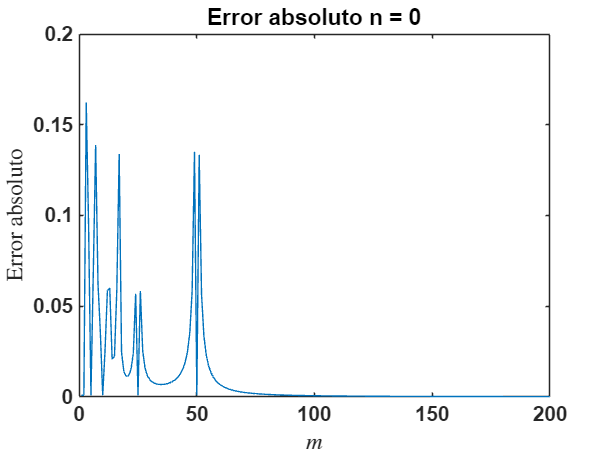

% Definimos la función dada
g = @(x) sin(100 * pi * x) .* (1 - x) .^ (1/2) .* log(1 - x);

% Vector con los n a utilizar
n = [0, 2, 5, 8];

% Valores de m a utilizar
m = 1:200;

% Valor exacto de la integral
I_g = 8.197612371239843e-04;

% Matriz para almacenar los errores absolutos
errores_abs = zeros(length(n), length(m));

% Bucle para calcular los errores absolutos
for i = 1:length(n)
    for j = 1:length(m)
        errores_abs(i, j) = abs(I_g - cuadraturaGComp([0, 1], m(j), n(i), g));
    end
end

% Graficamos el error absoluto para cada n en función del m
figure;
plot(m, errores_abs(1, :));
title('Error absoluto n = 0');
xlabel('$m$','Interpreter','latex');
ylabel('Error absoluto','Interpreter','latex');
set(gca,'FontName','Arial','FontSize',14,'FontWeight','Bold');

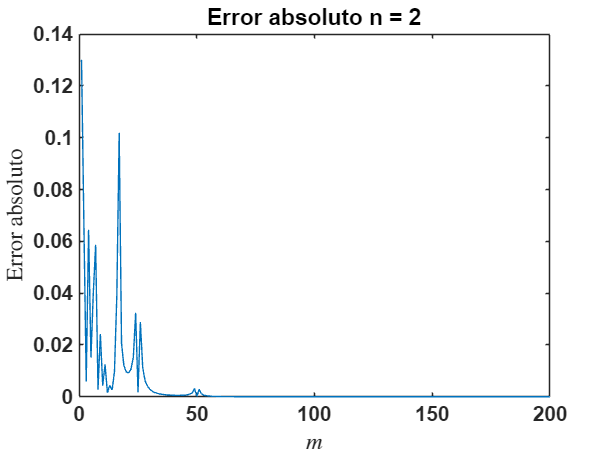


figure;
plot(m, errores_abs(2, :));
title('Error absoluto n = 2');
xlabel('$m$','Interpreter','latex');
ylabel('Error absoluto','Interpreter','latex');
set(gca,'FontName','Arial','FontSize',14,'FontWeight','Bold');

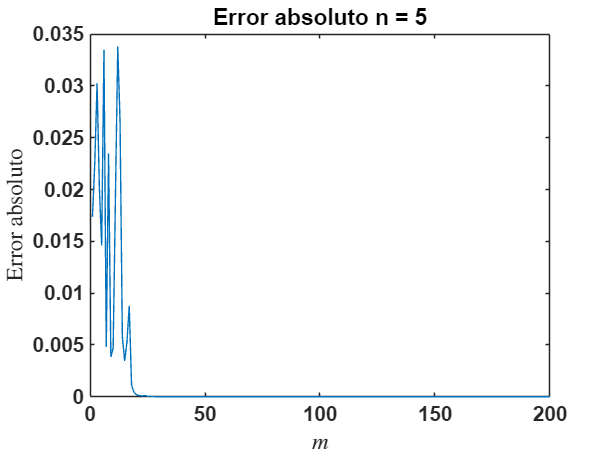


figure;
plot(m, errores_abs(3, :));
title('Error absoluto n = 5');
xlabel('$m$','Interpreter','latex');
ylabel('Error absoluto','Interpreter','latex');
set(gca,'FontName','Arial','FontSize',14,'FontWeight','Bold');

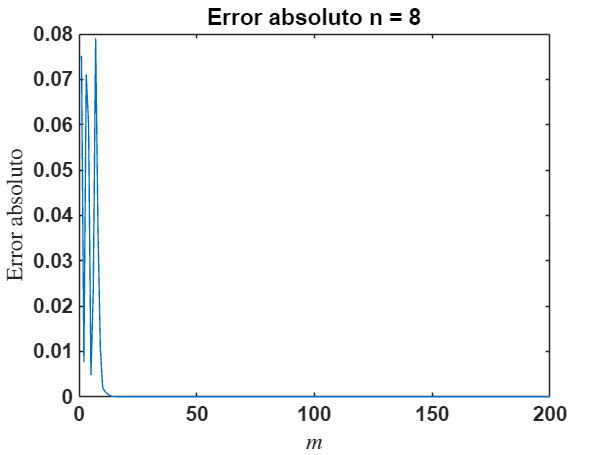


figure;
plot(m, errores_abs(4, :));
title('Error absoluto n = 8');
xlabel('$m$','Interpreter','latex');
ylabel('Error absoluto','Interpreter','latex');
set(gca,'FontName','Arial','FontSize',14,'FontWeight','Bold');

De los gráficos podemos observar que entre más grande es el número de subintervalos $m$, menor será el error absoluto obtenido. Asimismo, entre mayor es la cantidad de nodos $n$, menor será el error absoluto.

**Pregunta 4. **

En este ejercicio se busca construir una aproximación para la derivada de una función, a partir de su polinomio de interpolación de una manera diferente a las fórmulas estudiadas de $n + 1$ puntos del Capítulo 3.

**a)**

Para cualquier partición $\{ x_i \}_{i=0}^{n}$, se tienen las siguientes definiciones de coordenadas baricéntricas:

- 
$$L(x) = \prod_{k=0}^n (x-x_k)$$


- 
$$L'(x_k) = \prod_{i=0,i\neq k}^n (x_k-x_i)$$


- 
$$L_k(x) = \frac{L(x)}{L\prime(x_k) (x-x_k)}$$


- 
$$\lambda_k:= \frac{1}{L\prime(x_k)}$$


- 
$$\sum_{k=0}^n L_k(x) \equiv 1$$


Por 3, tenemos que:


$$L_k(x) = \frac{L(x)}{L\prime(x_k) (x-x_k)}
$$


Usando 4, se tiene:


$$\Longrightarrow L_k(x) = \frac{\lambda_k}{ (x-x_k)} \cdot L(x)
$$


Luego, por 5 se deduce que:


$$\Longrightarrow L_k(x) = \frac{\lambda_k}{ (x-x_k)} \cdot \frac{L(x)}{\sum_{k=0}^n L_k(x)} \hspace{0.5 cm} (!!)$$


Pero note que:


$$\frac{L(x)}{\sum_{k=0}^n L_k(x)} = \frac{1}{ \frac{\sum_{k=0}^n L_k(x)}{L(x)} }$$


Por 3:


$$\Longrightarrow  \frac{L(x)}{\sum_{k=0}^n L_k(x)} = \frac{1}{ \frac{\sum_{k=0}^n \frac{L(x)}{L\prime(x_k) \cdot (x-x_k)}}{L(x)} }$$


Cambiando de índice:


$$\Longrightarrow  \frac{L(x)}{\sum_{k=0}^n L_k(x)} = \frac{1}{ \sum_{j=0}^n \frac{1}{L\prime(x_j) \cdot (x-x_j)} }$$



$$\Longrightarrow  \frac{L(x)}{\sum_{k=0}^n L_k(x)} = \frac{1}{ \sum_{j=0}^n \frac{\lambda_j}{(x-x_j)} }$$


Regresando a $(!!)$:


$$L_k(x) = \left( \frac{\lambda_k}{ (x-x_k)} \right) / \left( \sum_{j=0}^n \frac{\lambda_j}{(x-x_j)} \right)$$


Ahora note que, si en la igualdad anterior multiplicamos ambos miembro por:


$$z(x) = \sum_{j=0}^n \frac{\lambda_j}{(x-x_j)}$$


Nos queda:


$$L_k(x) \cdot z(x) = \frac{\lambda_k}{ (x-x_k)}$$


Por último, si multiplicamos ambos miembros de la ecuación anterior por $(x - x_i)$, obtenemos el resultado deseado:

$L_k(x) \cdot s(x) = \lambda_k \cdot \frac{(x - x_i)}{ (x-x_k)}$, donde:


$$s(x) = \sum_{j=0}^n \lambda_j \cdot \frac{(x-x_i)}{(x-x_j)}$$


**b)**

En este caso es importante considerar 2 observaciones:

- $\lambda_k$ tiene un $k$ fijo, por lo que es constante.

- Del inciso anterior, se tiene que $L_k(x) \cdot s(x) = \lambda_k \cdot \frac{x-x_i}{x-x_k}$

Luego, usando $(2)$, note que:


$$L_k(x) \cdot s(x) = \lambda_k \cdot \frac{x-x_i}{x-x_k}$$



$$\Longrightarrow (L_k(x) \cdot s(x)) ' = \left(\lambda_k \cdot \frac{x-x_i}{x-x_k} \right) '$$


Usando regla del producto en ambos lados, tenemos:


$$\Longrightarrow L_k(x) \prime \cdot s(x) + L_k(x) \cdot s(x)\prime = \lambda_k \prime \cdot \frac{x-x_i}{x-x_k} + \lambda_k \cdot \left(\frac{x-x_i}{x-x_k} \right) '$$


Usando $(1)$:


$$\Longrightarrow L_k(x) \prime \cdot s(x) + L_k(x) \cdot s(x)\prime = \lambda_k \cdot \left(\frac{x-x_i}{x-x_k} \right) '$$


**c)**

Iniciamos expandiendo la expresión $s(x)$, de forma que esta es:


$$\displaystyle s(x)=\sum_{j=0}^n \lambda_j \cdot \frac{x-x_i}{x-x_j}$$



$$\Longrightarrow \displaystyle s(x) =  \lambda_1 \cdot \frac{x-x_i}{x-x_1} + \cdots + \lambda_{i - 1} \cdot \frac{x-x_i}{x-x_{i - 1}} + \lambda_{i} \cdot \frac{x-x_i}{x-x_{i}} + \lambda_{i + 1} \cdot \frac{x-x_i}{x-x_{i + 1}} + \cdots + \lambda_{n} \cdot \frac{x-x_i}{x-x_{n}}$$



$$\Longrightarrow \displaystyle s(x) =  \lambda_1 \cdot \frac{x-x_i}{x-x_1} + \cdots + \lambda_{i - 1} \cdot \frac{x-x_i}{x-x_{i - 1}} + \lambda_{i} + \lambda_{i + 1} \cdot \frac{x-x_i}{x-x_{i + 1}} + \cdots + \lambda_{n} \cdot \frac{x-x_i}{x-x_{n}}$$


Evaluando en $x_i$:


$$\Longrightarrow \displaystyle s(x_i) =  \lambda_1 \cdot \frac{x_i-x_i}{x_i-x_1} + \cdots + \lambda_{i - 1} \cdot \frac{x_i-x_i}{x_i-x_{i - 1}} + \lambda_{i} + \lambda_{i + 1} \cdot \frac{x_i-x_i}{x_i-x_{i + 1}} + \cdots + \lambda_{n} \cdot \frac{x_i-x_i}{x_i-x_{n}}$$



$$\Longrightarrow \displaystyle s(x_i) =  \lambda_1 \cdot \frac{0}{x_i-x_1} + \cdots + \lambda_{i - 1} \cdot \frac{0}{x_i-x_{i - 1}} + \lambda_{i} + \lambda_{i + 1} \cdot \frac{0}{x_i-x_{i + 1}} + \cdots + \lambda_{n} \cdot \frac{0}{x_i-x_{n}}$$



$$\Longrightarrow \displaystyle s(x_i) =  \lambda_i \hspace{1cm} (!)$$


Luego, de la igualdad del inciso anterior se obtiene que, con $i \neq k$:


$$\Longrightarrow L_k(x) \prime \cdot s(x) + L_k(x) \cdot s(x)\prime = \lambda_k \cdot \left(\frac{x-x_i}{x-x_k} \right) '$$



$$\Longrightarrow L_k(x) \prime \cdot s(x) + L_k(x) \cdot s(x)\prime = \lambda_k \cdot \left(\frac{(x-x_k) - (x - x_i)}{(x-x_k) ^ 2} \right)$$


Evaluando:


$$\Longrightarrow L_k(x_i) \prime \cdot s(x_i) + L_k(x_i) \cdot s(x_i)\prime = \lambda_k \cdot \left(\frac{(x_i-x_k) - (x_i - x_i)}{(x_i-x_k) ^ 2} \right)$$



$$\Longrightarrow L_k(x_i) \prime \cdot s(x_i) + L_k(x_i) \cdot s(x_i)\prime = \lambda_k \cdot \frac{(x_i-x_k)}{(x_i-x_k) ^ 2}$$



$$\Longrightarrow L_k(x_i) \prime \cdot s(x_i) + L_k(x_i) \cdot s(x_i)\prime = \lambda_k \cdot \frac{1}{(x_i-x_k)}$$


Por definición, si $L_k (x_i) = 0$, pues $i \neq k$:


$$\Longrightarrow L_k(x_i) \prime \cdot s(x_i) = \lambda_k \cdot \frac{1}{(x_i-x_k)}$$



$$\Longrightarrow L_k(x_i) \prime = \frac{\lambda_k}{s(x_i)} \cdot \frac{1}{(x_i-x_k)}$$


Y por $(!)$:


$$\Longrightarrow L_k(x_i) \prime = \frac{\lambda_k}{\lambda_i} \cdot \frac{1}{(x_i-x_k)}$$


**d)**

En clase se había demostrado la igualdad:


$$L_0 (x) + L_1 (x) + \cdots + L_{k - 1} (x) + L_k (x) + L_{k + 1} (x) + \dots + L_n (x) = 1$$


Derivando a ambos lados:


$$\Longrightarrow L_0 \prime (x) + L_1 \prime (x) + \cdots + L_{k - 1} \prime (x) + L_k \prime (x) + L_{k + 1} \prime (x) + \dots + L_n \prime (x) = 0$$


Evaluando:


$$\Longrightarrow L_0 \prime (x_k) + L_1 \prime (x_k) + \cdots + L_{k - 1} \prime (x_k) + L_k \prime (x_k) + L_{k + 1} \prime (x_k) + \dots + L_n \prime (x_k) = 0$$



$$\Longrightarrow L_k \prime (x_k) = - L_0 \prime (x_k) - L_1 \prime (x_k) - \cdots - L_{k - 1} \prime (x_k) - L_{k + 1} \prime (x_k) - \dots - L_n \prime (x_k)$$



$$\Longrightarrow L_k \prime (x_k) = - \sum_{i \neq k} L_i \prime (x_k)$$


**e)**

La matriz D está dada por:


$$\left[
\begin{array}{llllll}
L_0\prime(x_0) & L_1\prime(x_0) & \dots & L_n\prime(x_0) \\
L_0\prime(x_1) & L_1\prime(x_1) & \dots & L_n\prime(x_1) \\
\hspace{2.25mm} \vdots & \hspace{2.25mm} \vdots & \ddots_ & L_n\prime(x_2)\\
L_0\prime(x_n) & L_1\prime(x_n) & \dots & L_n\prime(x_n) \end{array} \right]$$


Haciendo $D \cdot f\left( \hat{x} \right)$:

$\left[
\begin{array}{llllll}
L_0\prime(x_0) & L_1\prime(x_0) & \dots & L_n\prime(x_0) \\
L_0\prime(x_1) & L_1\prime(x_1) & \dots & L_n\prime(x_1) \\
\hspace{2.25mm} \vdots & \hspace{2.25mm} \vdots & \ddots_ & \hspace{0.2cm} \vdots\\
L_0\prime(x_n) & L_1\prime(x_n) & \dots & L_n\prime(x_n) \end{array} \right] 

\cdot
\left[
\begin{array}{llllll}
f(\hat{x_0})  \\ 
f(\hat{x_1}) \\
\hspace{0.19cm} \vdots \\ 
f(\hat{x_n})
\end{array} \right]$,

obtenemos que la entrada $k$ del vector resultante, para $k \in \{ 0, 1, \dots, n \}$, está dada por:


$$\sum_{i=0}^{n} L_i\prime(x_k) \cdot f(\hat{x_i})$$


Lo cual corresponde a una aproximación de la derivada de $f(x)$ mediante las derivadas de los polinomios de Lagrange $\{L_i\}$, usando los nodos de Chebyshev $\{\hat{x_i}\}$.

Lo anterior basado en la definición del polinomio interpolador de Lagrange para $f(x)$, el cual está dado por:

 
$$p_n(x) = \sum_{k=0}^{n} L_k(x) \cdot f(x_i)$$


Por lo tanto, el vector $D \cdot f\left( \hat{x} \right)$ representa un conjunto de puntos que aproximan la derivada de $f(x)$, la cual es exacta en los nodos.

**f)**

En esta ocasión se investigó sobre las funciones [mtimes](https://la.mathworks.com/help/matlab/ref/mtimes.html), para multiplicar matrices y [setdiff](https://la.mathworks.com/help/matlab/ref/double.setdiff.html) para obtener los elementos de un vector sin uno en concreto (para los $L \prime$).

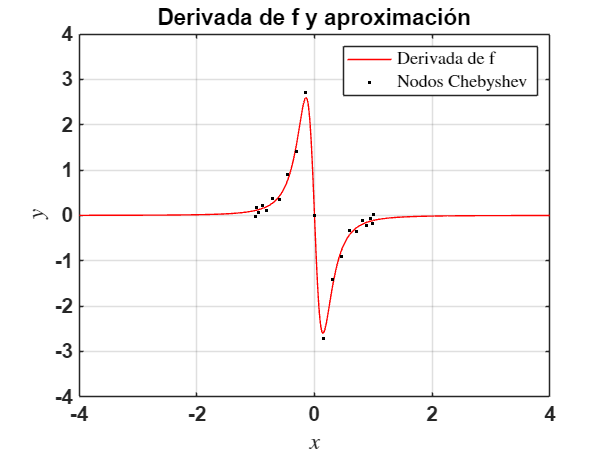

function D = calcularMatrizD(n)
    % Definimos los nodos de Chebyshev
    nodos_cheb = cos((0:n) * pi / n);
    
    % Definimos la matriz que tendrá las L'_k(xi)
    lk_primas = zeros(n + 1, n + 1);
    
    % Definimos el vector de las L'(xk)
    l_primas = zeros(1, n + 1);

    % Llenamos el vector anterior con sus respectivos valores
    for i = 1:(n + 1)
        l_primas(i) = prod(nodos_cheb(i) - setdiff(nodos_cheb, nodos_cheb(i)));
    end
    
    % Definimos los lambda_k
    lambda = 1 ./ l_primas;
    
    % Rellenamos la matriz de las L'_k(x_i)
    for i = 1:(n + 1)
        for k = 1:(n + 1)
            if(i ~= k)
                lk_primas(i, k) = lambda(k) / ( lambda(i) * (nodos_cheb(i) - nodos_cheb(k)) );
            end % fin if
        end % fin for j
        % Rellenamos la diagonal de la matriz
        lk_primas(i, i) = -sum(lk_primas(i, :));
    end % fin for i

    % Devolvemos la matriz D
    D = lk_primas;
end

% Definimos la función dada y su derivada
f = @(x) 1 ./ (1 + 16 * x.^2);
f_prima = @(x) (-32 * x) ./ ((1 + 16 * x.^2) .^2);

% Calculamos la matriz D con n = 20
D = calcularMatrizD(20);

% Nodos de Chebyshev para n = 20
nodos_cheb = (cos((0:20) * pi / 20)');

x = linspace(-4, 4, 1000);

% Valor de la derivada exacta
y_prima = f_prima(x);

% Aproximación de la derivada
y_prima_aprox = mtimes(D, f(nodos_cheb));

% Graficamos
figure
plot(x, y_prima, 'r', 'DisplayName', 'Derivada de f');

grid on;
hold on;

plot(nodos_cheb, y_prima_aprox, 'k.', 'DisplayName', 'Nodos Chebyshev');
ylim([-4, 4]);
legend('show','Interpreter','Latex');


title('Derivada de f y aproximación');
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
set(gca,'FontName','Arial','FontSize',14,'FontWeight','Bold');

**g)**

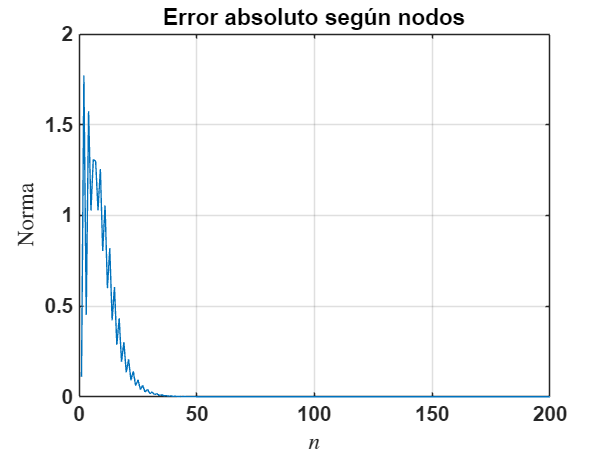

% Variables iniciales necesarias
n = 1:200;
vector_normas = zeros(length(n), 1);

% Ciclo para calcular la norma para cada n
for i = 1:length(n)
    nodos_cheb = (cos((0:i) * pi / i)');
    D = calcularMatrizD(i);
    
    % Se calculan la aproximación y el valor exacto de la derivada de f
    y_prima_aprox = D * f(nodos_cheb);
    y_prima = f_prima(nodos_cheb);

    % Guardamos la norma infinita
    vector_normas(i) = max(abs(y_prima_aprox - y_prima));
end

% Graficamos
figure
plot(n, vector_normas);

grid on;


title('Error absoluto según nodos');
xlabel('$n$','Interpreter','latex');
ylabel('Norma','Interpreter','latex');
set(gca,'FontName','Arial','FontSize',14,'FontWeight','Bold');


   4.3840e-14



% Se encuentra el error mínimo y el índice del mismo

   174



[minimo_error, n_min] = min(vector_normas);

% Se imprimen los resultados correspondientes
disp(minimo_error);
disp(n_min);

**Pregunta 5. **Es posible escribir el polinomio de interpolación de Lagrange $p$ en la base de los polinomios de Chebyshev, 


$$p(x) = \sum_{k = 0} ^ {n} c_k \cdot T_k (x), \hspace{1cm} |x| \leq 1,$$


donde $T_k (x) = cos(k \cdot arc cos(x))$. Sabemos que los polinomios de Chebyshev satisfacen la relación de recurrencia:


$$T_{k + 1}(x) = \alpha_k (x) \cdot T_k (x) + \beta_k (x) \cdot T_{k - 1} (x),$$


para $\alpha_k (x) = 2 \cdot x$ y $\beta_k (x) = -1$. Deseamos calcular $p(x_0)$ para $x_0$ dado (asumiendo que lo tenemos expresado en esta base). Para ello, considere el siguiente algoritmo:

Alg.1– Defina la sucesión $\{b_k (x_0)  \}_{k = 0} ^ {n + 2}$ mediante la recurrencia hacia atrás:


$$b_{n + 2} (x_0) = b_{n + 1} (x_0) = 0,$$


$b_k (x_0) = c_k + \alpha_k (x_0) \cdot b_{k + 1} (x_0) + \beta_{k + 1} (x_0) \cdot b_{k + 2} (x_0)$ para $k = n, n-1, \dots, 1$.

Se tiene entonces que el valor deseado es:


$$p(x_0) = T_0 (x_0) \cdot c_0 + T_1 (x_0) \cdot b_1 (x_0) + \beta_1 (x_0) \cdot T_0 (x_0) \cdot b_2 (x_0) \hspace{2cm} (2)$$


**a)**

Vamos construyendo la fórmula poco a poco, inicialmente:


$$\alpha_k (x_0) \cdot b_{k + 1} (x_0)$$


hay una multiplicación. Luego:


$$\beta_{k + 1} (x_0) \cdot b_{k + 2} (x_0)$$


es otra multiplicación. Al sumar los términos:


$$c_k + \alpha_k (x_0) \cdot b_{k + 1} (x_0) + \beta_{k + 1} (x_0) \cdot b_{k + 2} (x_0)$$


Tenemos 2 multiplicaciones en el segundo y tercer término, además, 2 sumas, por lo cual hay 4 operaciones para cada $b_k$. Note que para obtener un $b_{r}, \hspace{0.25cm} r < k$ hay que pasar por todos los $b_k$ anteriores, por ejemplo, para obtener $b_{k - 1}$ hay que hacer:


$$c_k + \alpha_k (x_0) \cdot b_{k + 1} (x_0) + \beta_{k + 1} (x_0) \cdot b_{k + 2} (x_0)$$


2 veces, es decir, 4 operaciones. En general, el algoritmo de los $b_k$ tiene un total de operaciones de $4 \cdot n$, pues se repiten las operaciones por cada $b_k$ extra, además, para determinar $p(x_0)$ se ocupan todos los $b_k$, pues estos se calculan de manera recursiva 'de adelante hacia atrás'.

Pasando propiamente a $p(x_0)$, note que tenemos 2 operaciones (multiplicaciones) más en este término:


$$\beta_1 (x_0) \cdot T_0 (x_0) \cdot b_2 (x_0)$$


Una extra en:


$$T_1 (x_0) \cdot b_1 (x_0)$$


Y una más en el término:


$$T_0 (x_0) \cdot c_0$$


Ahora, se agregan 2 sumas para formar $p(x_0)$:


$$p(x_0) = T_0 (x_0) \cdot c_0 + T_1 (x_0) \cdot b_1 (x_0) + \beta_1 (x_0) \cdot T_0 (x_0) \cdot b_2 (x_0)$$


Por lo cual, si sumamos la cantidad de operaciones para obtener los $b_k$ y las de $p(x_0)$ tenemos un total de:


$$4 \cdot n + 2 + 1 + 1 + 2$$



$$= 4 \cdot n + 6$$


operaciones en el algoritmo.

**b)**

La función vendría dada como sigue:

function y0 = evalCheb(c,x0)
    % Definimos un vector en donde guardar los b_k
    bk = [];

    % Definimos los primeros 2 valores, estos siempre están dados
    bk(1) = 0;
    bk(2) = 0;

    % El valor a_k es fijo en cada iteración, por lo que se calcula una
    % sola vez
    ak = 2 * x0;

    % Calculamos todos los bk
    for i = 1:(length(c))
        bk((i + 2)) = c((end - i + 1)) + ak * bk((i + 1)) - bk(i);
    end

    % Finalmente, se calcula p(x_0)
    y0 = c(1) + (x0 * bk((length(c) + 1))) - bk((length(c)));
end

**c)**

En primer lugar, calculamos los polinomios de Chebyshev correspondientes, se sebe que:

- 
$$T_0 (x) = 1$$


- 
$$T_1 (x) = x$$


Luego, siguiendo la relación de recurrencia:


$$T_{k + 1}(x) = 2 \cdot x \cdot T_k (x) - \cdot T_{k - 1} (x)$$


Tenemos:

- 
$$T_2 (x) = 2 \cdot x \cdot x - 1 = 2 \cdot x ^ 2 - 1$$


- 
$$T_3 (x) = 2 \cdot x \cdot (2 \cdot x ^ 2 - 1) - x = 4 \cdot x ^ 3 - 2 \cdot x - x = 4 \cdot x ^ 3 - 3 \cdot x$$


Entonces:


$$p(x) = c_0 \cdot T_0(x) + c_1 \cdot T_1(x) + c_2 \cdot T_2(x) + c_3 \cdot T_3(x)$$



$$\Longrightarrow p(x) = c_0 + c_1 \cdot x + c_2 \cdot (2 \cdot x ^ 2 - 1) + c_3 \cdot (4 \cdot x ^ 3 - 3 \cdot x)$$


Como el polinomio que buscamos tiene el término $x ^ 3$, tenemos que $c_3 = \frac{1}{4}$:


$$\Longrightarrow p(x) = c_0 + c_1 \cdot x + c_2 \cdot (2 \cdot x ^ 2 - 1) + x ^ 3 - \frac{3}{4} \cdot x$$


Luego, se tiene el término $-3 \cdot x ^ 2$, entonces $c_2 = -\frac{3}{2}$:


$$\Longrightarrow p(x) = c_0 + c_1 \cdot x -3 \cdot x ^ 2 + \frac{3}{2} + x ^ 3 - \frac{3}{4} \cdot x$$


Como no hay término $x$ en el polinomio, tenemos $c_1 = \frac{3}{4}$


$$\Longrightarrow p(x) = c_0 -3 \cdot x ^ 2 + \frac{3}{2} + x ^ 3$$


Finalmente, tenemos la constante $c_0 = -\frac{1}{2}$


$$\Longrightarrow p(x) = x ^ 3 - 3 \cdot x ^ 2 + 1$$


De esta forma tenemos el polinomio respectivo, entonces, usando la función tenemos:

% Se definen las constantes correspondientes

El polinomio con x0 = 1 es: -1.000000000000


ci = [-1/2 3/4 -3/2 1/4];

% Se guarda el algoritmo
px = evalCheb(ci, 1);

% Se imprime el resultado
fprintf('El polinomio con x0 = 1 es: %.12f\n', px)

**d)**

Para tomar el tiempo se buscó sobre la función [timeit](https://la.mathworks.com/help/matlab/performance-and-memory.html), además, se investigó sobre la función [polyval](https://la.mathworks.com/help/matlab/data_analysis/programmatic-fitting.html).

% Se definen las variables correspondientes
n = 10 ^ 8;
c = rand(n, 1);
x0 = 0.1;

% Se guardan los tiempos para sacar el promedio
tiempos_evalCheb = zeros(5, 1);
tiempos_polyval = zeros(5, 1);

% Se toma el tiempo de la función correspondiente
for i = 1:5
    tiempos_evalCheb(i) = timeit(@() evalCheb(c, x0));
    tiempos_polyval(i) = timeit(@() polyval(c, x0));
end

El tiempo promedio de la función evalCheb es: 8.069003430100


El tiempo promedio de la función polyval es: 0.955795530100


% Se calcula el promedio respectivo
prom_Cheb = mean(tiempos_evalCheb);
prom_polyval = mean(tiempos_polyval);

% Se imprimen los resultados
fprintf('El tiempo promedio de la función evalCheb es: %.12f\n', prom_Cheb)
fprintf('El tiempo promedio de la función polyval es: %.12f\n', prom_polyval)